load stability_large.mat %load once - 
% all data values are for beta = 10 deg
%note - variable omega_t is the gammadot from linkages_large.mlx

R = 0.9483; %wingspan in m
x_w = -0.0079 %0.0065%-0.0095022; %in m

x_w = -0.0079

z_w = -0.0201%-0.0192%-0.0228; %in m

z_w = -0.0201

u_t = 8.5; %m/s
C_m_ac = 0.025; %liebeck lpt
a = 2*pi; %airfoil slope
r = (cell2mat(span));
r = r(:,1:end-1)

r =          0    0.0399    0.0797    0.1196    0.1595    0.1785    0.2184    0.2583    0.2981    0.3380    0.3562    0.3961


c_r = cell2mat(c);
c_r = c_r(:,1:end-1)

c_r =     0.2086    0.1914    0.1795    0.1731    0.1722    0.1736    0.1627    0.1520    0.1428    0.1362    0.1349    0.0792


%lift and thrust in cartesian coordinates
alpha_b = deg2rad(5.5)

alpha_b = 0.0960

theta = alpha_b+alpharr

theta =     0.0756    0.0756    0.0756    0.0756    0.0756    0.0756    0.0756    0.0756    0.0756    0.0756    0.0756    0.0756    0.0756    0.0756    0.0756    0.0756    0.0756    0.0756    0.0756    0.0756    0.0756
    0.0636    0.0761    0.0886    0.0999    0.1087    0.1143    0.1161    0.1140    0.1081    0.0990    0.0876    0.0751    0.0626    0.0514    0.0425    0.0369    0.0351    0.0373    0.0432    0.0522    0.0636
    0.0515    0.0770    0.1023    0.1251    0.1430    0.1543    0.1579    0.1534    0.1413    0.1229    0.0997    0.0742    0.0489    0.0262    0.0083   -0.0030   -0.0066   -0.0022    0.0099    0.0284    0.0515
    0.0394    0.0780    0.1163    0.1507    0.1777    0.1947    0.2000    0.1932    0.1749    0.1468    0.1118    0.0732    0.0349    0.0006   -0.0264   -0.0434   -0.0488   -0.0420   -0.0236    0.0044    0.0394
    0.0274    0.0789    0.1300    0.1759    0.2119    0.2346    0.2417    0.2326    0.2081    0.1706    0.1239    0.0724    0.0212   -0.0246   -0.06

dT_new = (dT.*cos(theta)) + (dL.*sin(theta))

dT_new =     0.0041    0.0042    0.0047    0.0052    0.0057    0.0058    0.0057    0.0052    0.0047    0.0042    0.0041    0.0042    0.0047    0.0052    0.0057    0.0058    0.0057    0.0052    0.0047    0.0042    0.0041
   -0.0020    0.0042    0.0122    0.0209    0.0286    0.0334    0.0342    0.0309    0.0246    0.0171    0.0098    0.0035   -0.0012   -0.0046   -0.0067   -0.0080   -0.0087   -0.0089   -0.0082   -0.0060   -0.0020
   -0.0066    0.0046    0.0217    0.0421    0.0612    0.0734    0.0754    0.0668    0.0509    0.0324    0.0155    0.0030   -0.0042   -0.0067   -0.0065   -0.0060   -0.0068   -0.0091   -0.0115   -0.0115   -0.0066
   -0.0103    0.0052    0.0334    0.0695    0.1043    0.1270    0.1305    0.1142    0.0844    0.0508    0.0217    0.0027   -0.0047   -0.0023    0.0046    0.0100    0.0095    0.0027   -0.0068   -0.0131   -0.0103
   -0.0135    0.0062    0.0480    0.1044    0.1601    0.0403    0.0382    0.1754    0.1270    0.0733    0.0288    0.0027   -0.0028    0.0084    0.0

dL_new = (-dT.*sin(theta)) + (dL.*cos(theta))

dL_new =     0.1855    0.1876    0.1934    0.2006    0.2065    0.2087    0.2065    0.2006    0.1934    0.1876    0.1855    0.1876    0.1934    0.2006    0.2065    0.2087    0.2065    0.2006    0.1934    0.1876    0.1855
    0.1691    0.1960    0.2253    0.2528    0.2730    0.2806    0.2735    0.2538    0.2266    0.1977    0.1710    0.1482    0.1295    0.1151    0.1056    0.1020    0.1049    0.1138    0.1278    0.1463    0.1691
    0.1549    0.2043    0.2552    0.3016    0.3352    0.3483    0.3376    0.3062    0.2619    0.2127    0.1641    0.1187    0.0777    0.0434    0.0195    0.0099    0.0164    0.0375    0.0698    0.1096    0.1549
    0.1449    0.2162    0.2881    0.3526    0.3988    0.4167    0.4024    0.3603    0.3001    0.2319    0.1625    0.0953    0.0329   -0.0203   -0.0577   -0.0728   -0.0629   -0.0306    0.0183    0.0780    0.1449
    0.1406    0.2349    0.3285    0.4111    0.4690    0.2415    0.2206    0.4186    0.3426    0.2553    0.1647    0.0751   -0.0092   -0.0812   -0.1

gamma = atan(dT_new./dL_new)

gamma =     0.0220    0.0226    0.0242    0.0260    0.0275    0.0280    0.0275    0.0260    0.0242    0.0226    0.0220    0.0226    0.0242    0.0260    0.0275    0.0280    0.0275    0.0260    0.0242    0.0226    0.0220
   -0.0117    0.0214    0.0540    0.0825    0.1044    0.1186    0.1243    0.1210    0.1083    0.0865    0.0573    0.0239   -0.0096   -0.0397   -0.0634   -0.0784   -0.0832   -0.0780   -0.0637   -0.0410   -0.0117
   -0.0425    0.0223    0.0847    0.1388    0.1805    0.2078    0.2196    0.2147    0.1919    0.1512    0.0943    0.0252   -0.0541   -0.1543   -0.3244   -0.5450   -0.3937   -0.2390   -0.1635   -0.1042   -0.0425
   -0.0707    0.0243    0.1155    0.1947    0.2558    0.2960    0.3135    0.3069    0.2744    0.2155    0.1327    0.0279   -0.1405    0.1141   -0.0798   -0.1368   -0.1500   -0.0870   -0.3574   -0.1658   -0.0707
   -0.0959    0.0263    0.1452    0.2488    0.3289    0.1655    0.1713    0.3967    0.3551    0.2797    0.1733    0.0355    0.2902   -0.1027   -0.19

%omega_t(1) = 6.84380802101635e-15
% omega_t(11) = 1
% omega_t(21) = 1
omega_t = ones(12,1)*gammadot

omega_t =          0   -8.2604  -14.0984  -17.1351  -18.0430  -17.3888  -15.5629  -12.8274   -9.2775   -4.9285   -0.0000    4.9285    9.2775   12.8274   15.5629   17.3888   18.0430   17.1351   14.0984    8.2604    0.0000
         0   -8.2604  -14.0984  -17.1351  -18.0430  -17.3888  -15.5629  -12.8274   -9.2775   -4.9285   -0.0000    4.9285    9.2775   12.8274   15.5629   17.3888   18.0430   17.1351   14.0984    8.2604    0.0000
         0   -8.2604  -14.0984  -17.1351  -18.0430  -17.3888  -15.5629  -12.8274   -9.2775   -4.9285   -0.0000    4.9285    9.2775   12.8274   15.5629   17.3888   18.0430   17.1351   14.0984    8.2604    0.0000
         0   -8.2604  -14.0984  -17.1351  -18.0430  -17.3888  -15.5629  -12.8274   -9.2775   -4.9285   -0.0000    4.9285    9.2775   12.8274   15.5629   17.3888   18.0430   17.1351   14.0984    8.2604    0.0000
         0   -8.2604  -14.0984  -17.1351  -18.0430  -17.3888  -15.5629  -12.8274   -9.2775   -4.9285   -0.0000    4.9285    9.2775   12.8274   15.

%omega_t = 4.7997
J_t = u_t./(R.*omega_t) %instantaeous advance ratio

J_t = 	1.0e+15 *

       Inf   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -4.5583    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    1.3097
       Inf   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -4.5583    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    1.3097
       Inf   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -4.5583    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    1.3097
       Inf   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -4.5583    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    1.3097
       Inf   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -4.5583    0.0000    0.0000    0.00

r = r'*ones(1,21);
c_r = c_r'*ones(1,21)

c_r =     0.2086    0.2086    0.2086    0.2086    0.2086    0.2086    0.2086    0.2086    0.2086    0.2086    0.2086    0.2086    0.2086    0.2086    0.2086    0.2086    0.2086    0.2086    0.2086    0.2086    0.2086
    0.1914    0.1914    0.1914    0.1914    0.1914    0.1914    0.1914    0.1914    0.1914    0.1914    0.1914    0.1914    0.1914    0.1914    0.1914    0.1914    0.1914    0.1914    0.1914    0.1914    0.1914
    0.1795    0.1795    0.1795    0.1795    0.1795    0.1795    0.1795    0.1795    0.1795    0.1795    0.1795    0.1795    0.1795    0.1795    0.1795    0.1795    0.1795    0.1795    0.1795    0.1795    0.1795
    0.1731    0.1731    0.1731    0.1731    0.1731    0.1731    0.1731    0.1731    0.1731    0.1731    0.1731    0.1731    0.1731    0.1731    0.1731    0.1731    0.1731    0.1731    0.1731    0.1731    0.1731
    0.1722    0.1722    0.1722    0.1722    0.1722    0.1722    0.1722    0.1722    0.1722    0.1722    0.1722    0.1722    0.1722    0.1722    0.1722

% %solving for phi - included angle
% syms phi;
% V_w = ((r.*R.*omega_t).^2 + u_t.^2 - 2.*r.*R.*omega_t.*u_t.*cos(phi)).^0.5;
% eta = atan((u_t.*sin(phi))./((r.*R.*omega_t) - (u_t.*cos(phi))));
% %eta = asin((u_t*sin(phi))./(V_w));
% %eta = acos(((r.*R.*omega_t).^2 + V_w.^2 - u_t^2)./(2.*r.*R.*omega_t.*V_w));
% solution = u_t.*sin(phi) - V_w.*sin(eta)==0;
% S = fsolve(solution,phi)

% %solving for phi - included angle
% syms phi
% i = 2
% j = 2
% %V_w = @(phi) ((r.*R.*omega_t).^2 + u_t.^2 - 2.*r.*R.*omega_t.*u_t.*cos(phi)).^0.5;
% %eta = @(phi) atan((u_t.*sin(phi))./((r.*R.*omega_t) - (u_t.*cos(phi))));
% %eta = asin((u_t*sin(phi))./(V_w));
% %eta = acos(((r.*R.*omega_t).^2 + V_w.^2 - u_t^2)./(2.*r.*R.*omega_t.*V_w));
% F = u_t.*sin(phi) - (((r(i).*R.*omega_t(j)).^2 + u_t.^2 - 2.*r(i).*R.*omega_t(j).*u_t.*cos(phi)).^0.5).*sin(atan((u_t.*sin(phi))./((r(i).*R.*omega_t(j)) - (u_t.*cos(phi)))));%==0;
% %x0 = [0 2*pi];
% x = solve(F, phi)
% vpa(x)

phi = deg2rad(90)

phi = 1.5708

l = (x_w.*cos(gamma) + z_w.*sin(gamma))./(c_r);
m = (r./J_t).*(2.*alpharr.*sin(phi) - cos(phi)) + 1;
n = (z_w.*cos(gamma) + x_w.*sin(gamma))./(c_r);
o = alpharr.*(1-((r./J_t).*cos(phi)));
p = C_m_ac.*((2.*r.*sin(phi))./(J_t.*a));
dCm_dalpha = (l.*m + n.*o + p)*a

dCm_dalpha =    -0.2387   -0.2391   -0.2400   -0.2411   -0.2420   -0.2423   -0.2420   -0.2411   -0.2400   -0.2391   -0.2387   -0.2391   -0.2400   -0.2411   -0.2420   -0.2423   -0.2420   -0.2411   -0.2400   -0.2391   -0.2387
   -0.2304   -0.2625   -0.2931   -0.3191   -0.3388   -0.3511   -0.3556   -0.3517   -0.3392   -0.3185   -0.2911   -0.2598   -0.2283   -0.2000   -0.1776   -0.1635   -0.1589   -0.1640   -0.1784   -0.2011   -0.2304
   -0.2156   -0.2831   -0.3453   -0.3968   -0.4351   -0.4593   -0.4690   -0.4631   -0.4404   -0.4003   -0.3442   -0.2759   -0.1997   -0.1112    0.0207    0.1774    0.0779   -0.0307   -0.0927   -0.1508   -0.2156
   -0.1944   -0.2978   -0.3909   -0.4654   -0.5193   -0.5534   -0.5679   -0.5618   -0.5320   -0.4758   -0.3927   -0.2860   -0.1311   -0.2750   -0.1194   -0.0657   -0.0520   -0.1000    0.0664   -0.0920   -0.1944
   -0.1685   -0.3036   -0.4233   -0.5153   -0.5791   -0.4927   -0.5024   -0.6340   -0.6024   -0.5362   -0.4320   -0.2909   -0.4071   -0.1041   

time_angle = linspace(0,2*pi,21)

time_angle =          0    0.3142    0.6283    0.9425    1.2566    1.5708    1.8850    2.1991    2.5133    2.8274    3.1416    3.4558    3.7699    4.0841    4.3982    4.7124    5.0265    5.3407    5.6549    5.9690    6.2832


r_contour = cell2mat(span)

r_contour =          0    0.0399    0.0797    0.1196    0.1595    0.1785    0.2184    0.2583    0.2981    0.3380    0.3562    0.3961    0.4360


r_contour = r_contour(:,1:end-1)

r_contour =          0    0.0399    0.0797    0.1196    0.1595    0.1785    0.2184    0.2583    0.2981    0.3380    0.3562    0.3961


[X,Y] = meshgrid(time_angle,r_contour)

X =          0    0.3142    0.6283    0.9425    1.2566    1.5708    1.8850    2.1991    2.5133    2.8274    3.1416    3.4558    3.7699    4.0841    4.3982    4.7124    5.0265    5.3407    5.6549    5.9690    6.2832
         0    0.3142    0.6283    0.9425    1.2566    1.5708    1.8850    2.1991    2.5133    2.8274    3.1416    3.4558    3.7699    4.0841    4.3982    4.7124    5.0265    5.3407    5.6549    5.9690    6.2832
         0    0.3142    0.6283    0.9425    1.2566    1.5708    1.8850    2.1991    2.5133    2.8274    3.1416    3.4558    3.7699    4.0841    4.3982    4.7124    5.0265    5.3407    5.6549    5.9690    6.2832
         0    0.3142    0.6283    0.9425    1.2566    1.5708    1.8850    2.1991    2.5133    2.8274    3.1416    3.4558    3.7699    4.0841    4.3982    4.7124    5.0265    5.3407    5.6549    5.9690    6.2832
         0    0.3142    0.6283    0.9425    1.2566    1.5708    1.8850    2.1991    2.5133    2.8274    3.1416    3.4558    3.7699    4.0841    4.3982  

Y =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0399    0.0399    0.0399    0.0399    0.0399    0.0399    0.0399    0.0399    0.0399    0.0399    0.0399    0.0399    0.0399    0.0399    0.0399    0.0399    0.0399    0.0399    0.0399    0.0399    0.0399
    0.0797    0.0797    0.0797    0.0797    0.0797    0.0797    0.0797    0.0797    0.0797    0.0797    0.0797    0.0797    0.0797    0.0797    0.0797    0.0797    0.0797    0.0797    0.0797    0.0797    0.0797
    0.1196    0.1196    0.1196    0.1196    0.1196    0.1196    0.1196    0.1196    0.1196    0.1196    0.1196    0.1196    0.1196    0.1196    0.1196    0.1196    0.1196    0.1196    0.1196    0.1196    0.1196
    0.1595    0.1595    0.1595    0.1595    0.1595    0.1595    0.1595    0.1595    0.1595    0.1595    0.1595    0.1595    0.1595    0.1595    0.1595  

%plot(time_angle,dCm_dalpha(1,:),'*')
figure
contourf(X,Y, dCm_dalpha,150, 'edgecolor', 'none')
%shading interp;
%colormap jet;
xlabel ('Flapping Cycle Angle (in rad)')
ylabel ('Spanwise  Location (in m)')
%title('m = 0; correlation time = 1.0', 'FontName','Times', 'FontSize', 12)
axis()

ans =          0    6.2832         0    0.3961


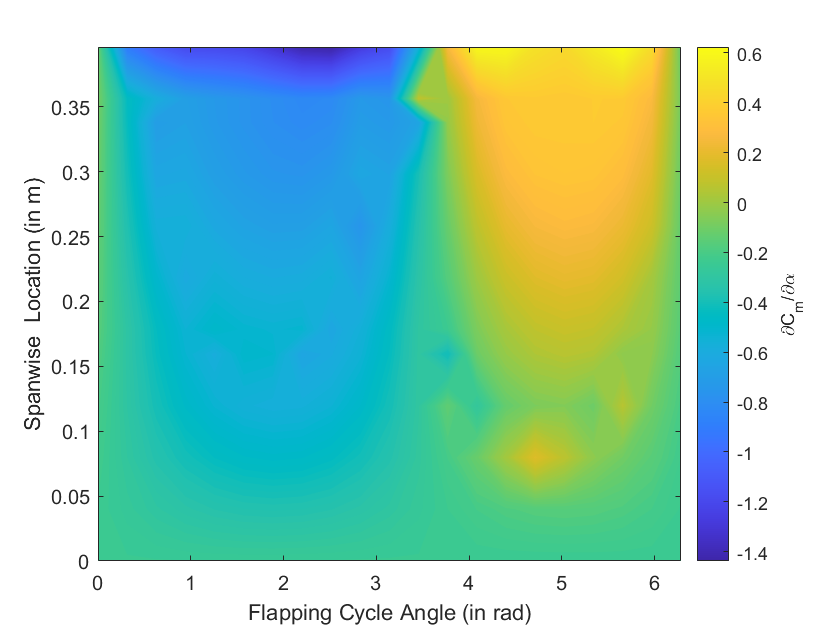

a = colorbar;
a.Label.String = '\partialC_m/\partial\alpha';